# 3.1 Random Process Experiments

Alexandre Rey, MSE, Ma-StatDig, 07.03.22

clear;
rng('default');
rand(1);    % keep it to get same results as teacher

## Random phase sinusoid (example 3.3.1)

Consider as random process a random phase sinusoid:

$x(n) = Asin(n\omega_0+\phi)$     (1)

Here $n$ is the sample number $\omega_0$ is a constant value in rad/sample and $\phi$ is the random variable in this process, and it is uniform distributed from $-\pi \dots +\pi$ the probability density function is given by:


$$f_\phi(\alpha) =
  \begin{cases}
    (2 \pi)^{-1} & \alpha \in [-\pi\cdots \pi]\\
    0                &  \text{otherwise}
  \end{cases}$$
 

First define $N_R$ values of $\phi $with the function `rand()` (uniform distribution) then define the $N$ samples of each realization of (1).

N = 1000;       % number of points
n = 0:N-1;
NR = 100;       % number of realizations
nr = 0:NR-1;
A = 1;          % amplitude
F0 = 1/50;      % frequency [Hz]
w0 = 2*pi*F0;   % angular frequency [rad/s]

disp(table(N, NR, A, F0, w0));

     N      NR     A     F0       w0   
    ____    ___    _    ____    _______

    1000    100    1    0.02    0.12566



% NR random values between -pi and pi
phi = 2 * pi * (rand(NR,1) - 0.5);

% NR random processes of N samples
xn = A .* sin(n*w0 + phi);
disp(['Size of xn = ' num2str(size(xn,1)) 'x' num2str(size(xn,2))]);

Size of xn = 100x1000


Each line is a realization and each column is a sample.			

Plot the time sequence for realizations from `nr=1:3` and plot the sample $x(3)$ fo all the $R$ realizations:

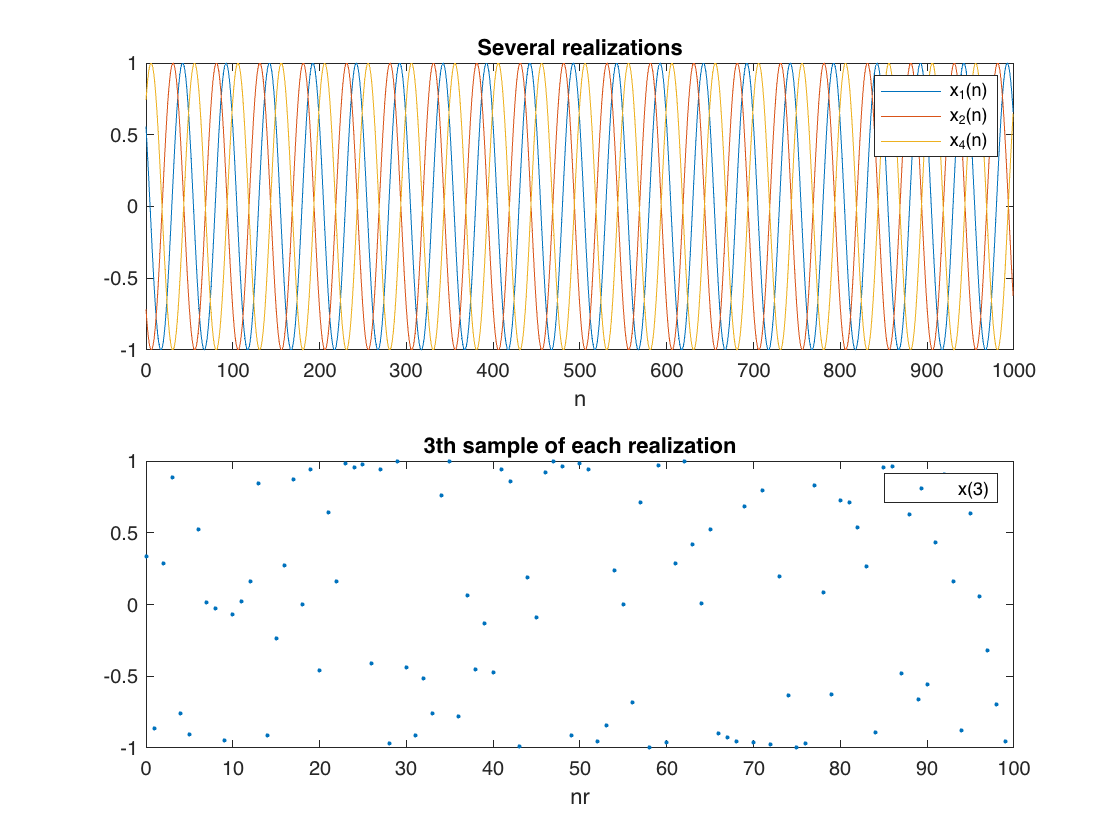

nr_p = [1 2 4]; % realizations to plot
xn_p = 3;       % sample to plot

figure;
subplot(2,1,1);
    hold on;
    for i=nr_p
       plot(n, xn(i,:), 'DisplayName', sprintf('x_%1d(n)',i));
    end
    hold off;
    xlabel('n');
    title('Several realizations');
    box on;
    legend('Location','northeast');
subplot(2,1,2);
    plot(nr, xn(:,xn_p), '.');
    legend('x(3)');
    xlabel('nr');
    title([num2str(xn_p) 'th sample of each realization']);

## Mean of the process


$$m_x(n) = E\{x(n)\}=\sum_ka_k\text{Pr}\{x=a_k\}$$
 

For each sample value of $n$ we could compute the arithmetic mean over all the realizations, in theory with a infinite number of realizations we should have $m_x(n) = 0$

Estimate the mean of the process $x(n)$:

% mean of each sample on all realizations
% manually computed mean: mxn = sum(xn) / NR
mxn = mean(xn, 1);

mxn =     0.0389    0.0310    0.0225    0.0137    0.0047   -0.0044   -0.0134   -0.0222   -0.0307   -0.0386   -0.0460   -0.0526   -0.0584   -0.0633   -0.0672   -0.0700   -0.0718   -0.0724   -0.0718   -0.0701   -0.0673   -0.0635   -0.0586   -0.0529   -0.0463   -0.0389   -0.0310   -0.0225   -0.0137   -0.0047    0.0044    0.0134    0.0222    0.0307    0.0386    0.0460    0.0526    0.0584    0.0633    0.0672    0.0700    0.0718    0.0724    0.0718    0.0701    0.0673    0.0635    0.0586    0.0529    0.0463


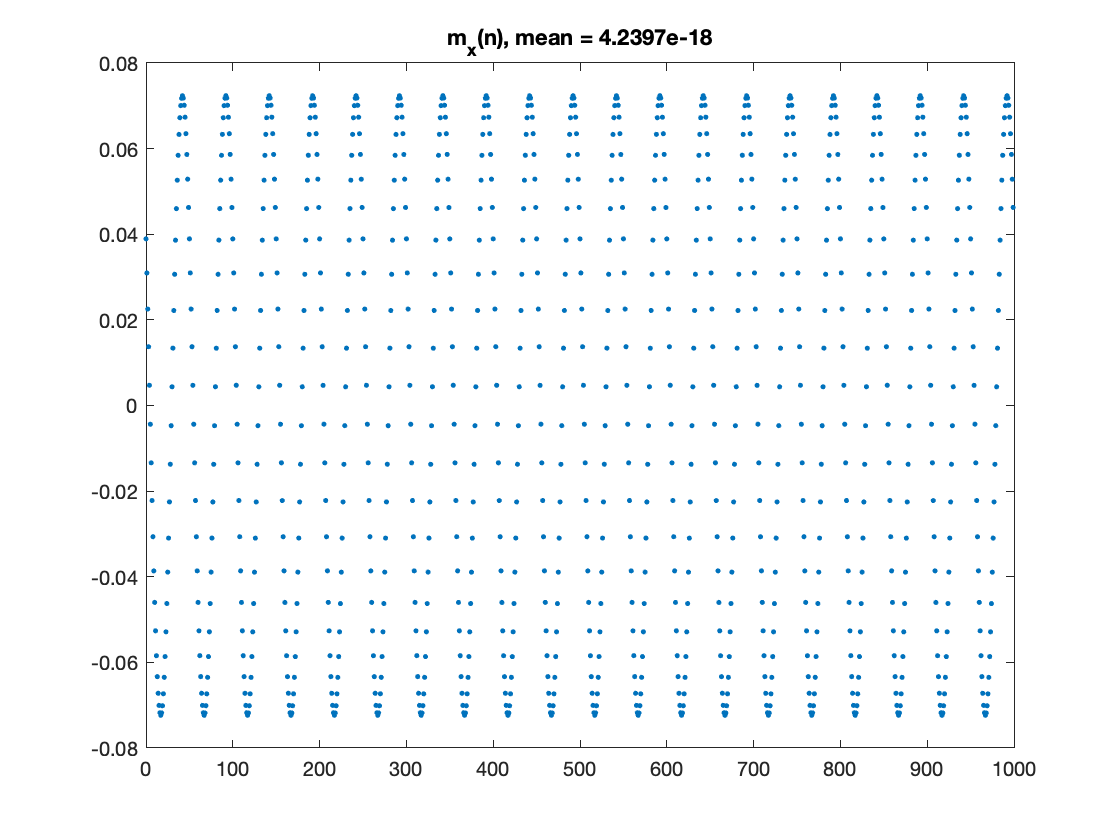

figure;
    plot(n, mxn, '.');
    title(['m_x(n), mean = ' num2str(mean(mxn))]);

In this case we notice the mean of the process is very close to 0 so the process is called *zero mean process*.

And *th *variance of the process:

% manually computed variance: varxn = sum((xn-mxn) .^2) / (NR-1)
varxn = var(xn, 0, 1); % normalized by NR-1

varxn =     0.5197    0.5221    0.5233    0.5231    0.5216    0.5190    0.5153    0.5107    0.5057    0.5004    0.4953    0.4906    0.4867    0.4837    0.4820    0.4815    0.4823    0.4844    0.4876    0.4917    0.4966    0.5017    0.5070    0.5119    0.5163    0.5197    0.5221    0.5233    0.5231    0.5216    0.5190    0.5153    0.5107    0.5057    0.5004    0.4953    0.4906    0.4867    0.4837    0.4820    0.4815    0.4823    0.4844    0.4876    0.4917    0.4966    0.5017    0.5070    0.5119    0.5163


Repeating the signal $N_R$ times, the mean value waveform $\frac{1}{N_R}\sum_{k=1}^{N_R}x_k(n)$ approaches to zero when $N_R\rightarrow \infty$. The theory is confirmed. This shows that $x(n)$ is not predicatable, Thus, a random signal $x(n)$ is unrepeatable and unpredictable.

## Second order moments of the process

We could compute the autocorrelation of the process $x(n)$ theoretically $r_x(k,l) = E\{x(k)x(l)\}$ between two samples $k$, $l$ over all the realizations and this is in theory given by: $r_x(k,l) = E\{x(k)x(l)\} = \frac{1}{2}A^2 cos((k-l)\omega_0)$

k=0;        % we test it with k=0
rx = 0.5 .* A.^2 .* cos(k-n*w0);

In order to verify it, estimate numerically with the matrix of data `xn` the autocorrelation matrix `Rxx`, that is the product between samples number $k$ for each realization by sample $l$ for each realization the scalar product $\hat{r_x}(k,l)= \frac{1}{N_R}x(k)^T x(l) $ multiplying matrix `xn` themselves we obtain the matrix `Rxx` who is symmetric.

The autocorrelation matrix is equal to the covariance matrix because the process is zero mean.

Rxx = 1/NR .* (xn'*xn);

Rxx =     0.5160    0.5131    0.5021    0.4832    0.4567    0.4229    0.3825    0.3361    0.2844    0.2281    0.1683    0.1058    0.0417   -0.0231   -0.0876   -0.1506   -0.2113   -0.2687   -0.3218   -0.3698   -0.4120   -0.4477   -0.4764   -0.4975   -0.5108   -0.5160   -0.5131   -0.5021   -0.4832   -0.4567   -0.4229   -0.3825   -0.3361   -0.2844   -0.2281   -0.1683   -0.1058   -0.0417    0.0231    0.0876    0.1506    0.2113    0.2687    0.3218    0.3698    0.4120    0.4477    0.4764    0.4975    0.5108
    0.5131    0.5179    0.5144    0.5028    0.4833    0.4562    0.4219    0.3809    0.3340    0.2817    0.2250    0.1648    0.1020    0.0375   -0.0275   -0.0921   -0.1553   -0.2160   -0.2732   -0.3262   -0.3741   -0.4160   -0.4514   -0.4796   -0.5003   -0.5131   -0.5179   -0.5144   -0.5028   -0.4833   -0.4562   -0.4219   -0.3809   -0.3340   -0.2817   -0.2250   -0.1648   -0.1020   -0.0375    0.0275    0.0921    0.1553    0.2160    0.2732    0.3262    0.3741    0.4160    0.4514    0.4796   

Each element of Rxx is an estimate $\hat{r_x}(k,l)
$ and is close to ${r_x}(k,l)
$ for large $N_R$ realizations. If we plot the first line of Rxx $R_x(1,l) = \hat{r_x}(k=0,l)
$ and we compare to the plot of the theoric fuction ${r_x}(k,l)
$ for $k=0$, we have:

erx = rx - Rxx(1,:);

figure;
    plot(n, Rxx(1,:), ...
         n, rx, ...
         n, erx);
    xlabel('k-l');
    xlim([0, 2/F0]);
    ylim([min(rx), max(rx)]);
    legend('$R_x(k=0,l)$', '$r_x(k=0,l)$', 'error', ...
           'Interpreter', 'latex');
    grid;

We could observe that if we increase the number of sample per realization we don't reduce the estimation error of the correlation $r_x$, but if we increase the number of realizations $N_R$ the error is reduced.

## Autocorrelation of a sum of process (example 3.3.3)

Consider the exemple in slide 45. $y(n)$ is a sum of 2 random processes: A sum of $M$ sinosoids with a random phase like the process $x(n)$ above and the white gaussian noise $v(n)$. 


$$y(n) = y_h(n) + v(n) =\left[ \sum_{m=1}^{M} A_m sin(n \omega_m + \phi_m) \right ]   +   v(n) $$
 

In the exemple $A_m = A$ and $\omega_m = \omega_0$ are constants with $m$, and $\phi_m$ a random variable uniformly distributed like in the above exemple.

First create $y(n)$ process using the matrix previously defined `xn` and use the function `randn` to generate the white gaussian noise.

With `M = 5 `and `wm = w0*m `and `Am = A0/m `with `phim` a uniform distrubutes phase like in ex 3.1.1, compute the sum of the harmonic process $y_h(n)$ and the gaussian noise $v(n)$ produced with the function `randn()` with a std of A0.

% Gaussian white noise
M = 5;
m = 1:M;
wm = w0 .* m        % M angular frequency (rad/s)

wm =     0.1257    0.2513    0.3770    0.5027    0.6283


A0 = M;
Am = A0./m

Am =     5.0000    2.5000    1.6667    1.2500    1.0000


phim = 2.*pi.* (rand(1,M) - 0.5)     % 5 random phases between -pi and pi

phim =     1.8490   -1.1862    0.1793   -2.1008    0.6408


yh = Am' .* sin(wm'*n + phim');
yh = sum(yh, 1);

vn = A0 * randn(1,N);             % gaussian noise

yn = yh + vn;

figure;
    plot(n, yh, 'LineWidth', 1.5);
    hold on;
    plot(n, yn);
    hold off;
    xlabel('n');
    legend('y_h(n)', 'y(n) = y_h(n) + v(n)');
    title(['y_h(n): sum of ' num2str(M) ' random phase sinus']);

If we compute the autocorrelation of the harmonic process $y_h(n)$ called $r_{yh}(k)$ and the autocorrealation of the noise $v(n)$ called $r_v(k)$ we try to show that the autocorrelation of $y(n)
$ called $r_y(k)
$ is the summ of the autocorrelation of $y_h$ and $v(n)$:


$$r_y(k) = r_{yh}(k) + r_v(k)$$


that is the case if the 2 process are uncorrelated, which is the case here.

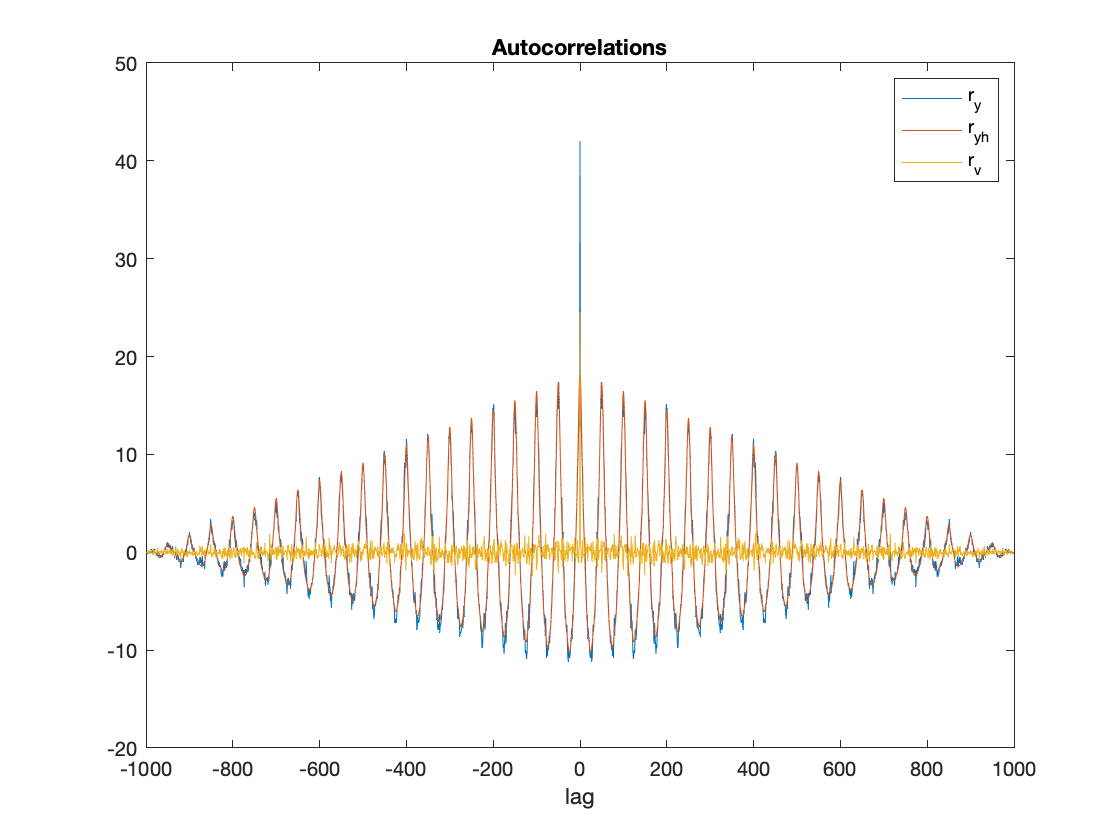

% biased indicates to normalize by N
[ryh, lagyh] =  xcorr(yh, 'biased');
[rv , lagv]  =  xcorr(vn, 'biased');
[ry , lagy]  =  xcorr(yn, 'biased');

figure
    plot(lagy, ry, ...
         lagyh, ryh, ...
         lagv, rv);
    title('Autocorrelations');
    xlabel('lag');
    legend('r_y', 'r_{yh}', 'r_v');

% check that r_y[k] = r_yh[k] + r_v[k]
k = 0;
rv_k = rv(lagv==k);
ryh_k = ryh(lagyh==k);
ry_k = ry(lagy==k);
disp(['r_yh[' num2str(k) '] + rv[' num2str(k) '] = ' num2str(ryh_k) ' + ' num2str(rv_k) ' = ' num2str(rv_k+ryh_k)]);

r_yh[0] + rv[0] = 18.2951 + 24.548 = 42.8431


disp(['r_y[' num2str(k) '] = ' num2str(ry_k)]);

r_y[0] = 42.0194


clear k rv_k ryh_k ry_k

## The power spectrum

The power spectrum or power spectral density is the the discrete-time Fourier transform of the autocorrelation sequence $r_x(k)$ in ex 3.3.1:


$$P_x(e^{j\omega}) = \sum _ {k= -\infty}^{+\infty} r_x(k) e^{-jk\omega}$$


Since $r_x(k)$ is always symetric, the spectrum is real and non-negative $P_x(e^{j\omega}) \ge 0$.

If we take as exemple the previous harmonic process $x(n)$ we could compute the power spectrum $P_x(e^{j\omega})$, compare the theoric $r_x$ and the numerical estimation of $r_x$ based on the marix `Rx`:

Px_ejw = 1/N * fftshift(fft(Rxx(2,:)));
Pxth_ejw = 1/N * fftshift(fft(rx));
F = -0.5 : 1/N : 0.5-1/N;

An interesting property is that the sum of the power spectrum is the power of the process, ths variance, verify with your data and the theoric spectrum


$$E\{ |x(n)|^2\} =\int _ {F= -1/2}^{+1/2}  P_x(e^{j2 \pi F} ) dF =  \sum _ {k= -N/2}^{+N/2}  P_x(k ) $$


Var_xth = sum(Pxth_ejw)

Var_xth = 0.5000 + 0.0000i

Var_x = sum(Px_ejw)

Var_x = 0.5131 + 0.0000i

Varxn = varxn(1)

Varxn = 0.5197

Plot the spectrum amplitude in dB (10* log10 ( abs(Px)))....

figure
subplot(2,1,1)
    plot(F, 10*log10(abs(Px_ejw)), ...
         F, 10*log10(abs(Pxth_ejw)))
    ylabel('Px(f) [dB]')
    xlabel('f [-]')
    legend('Px','Pxth')
    grid;
    xlim([-0.5,0.5])
    ylim([-200,0])
subplot(2,1,2)
    plot(F, real(Px_ejw), '.-', ...
         F, real(Pxth_ejw), '+-')
    ylabel('Px(f) [-]')
    xlabel('f [-]')
    legend('Px','Pxth')
    grid;
    xlim([-0.05,0.05])
    ylim([-0.050,0.3])

 % We get the spikes at ±F0 = ±0.02
[VRx,DRx] = eig(Rxx);
Lambdamax = max(diag(DRx))

Lambdamax = 259.2701

Lambdamin = min(diag(DRx)) %

Lambdamin = -6.5726e-14

**Property of the power spectrum of a WSS random process:**

4. - *Eigenvalue Extremal Property.* The eigenvalues of the $n \times  n$ autocorrelation matrix of a zero mean WSS random process are upper and lower bounded by the maximum and minimum values, respectively, of the power spectrum, $min_\omega P_x(e^{j\omega}) \; \le  \; \lambda_i \; \le  \; max_\omega P_x(e^{j\omega})$

## Filtering Random Process

We consider a Gaussian noise as random process $\omega_n$ with variance $\sigma_w^2  = 1$ and we apply a discrete filter to this process, the filter is defined by his transfer function $H(z)
$, and in our exemple is a FIR 10 tap MA filter:

(previously a first order low pass filter $H(z) = \frac{1}{1-0.25z^{-1}}$)

sigmaw = 1;
wn = sigmaw .* randn(NR, N);
%Num = [1,0]
%Den =[1, -0.25]

% a) FIR MA 10 taps
Num = 0.1.*ones(1,10);
Den = [1 zeros(1,9)];
printsys(Num, Den, 'z')

 
num/den = 
 
   0.1 z^9 + 0.1 z^8 + 0.1 z^7 + 0.1 z^6 + 0.1 z^5 + 0.1 z^4 + 0.1 z^3
   + 0.1 z^2 + 0.1 z + 0.1
   -------------------------------------------------------------------
                                   z^9


Compute the impulse response over the N samples and the frequency response .

% returns the N-point complex frequency response vector H
% and the N-point frequency vector W in radians/sample
[H, W] = freqz(Num, Den, N);

dn = [1 zeros(1,N)];       % unit impulse
h = filter(Num, Den, dn);

figure
subplot(2,1,1);
    plot(W/2/pi, abs(H));
    xlabel('f[-]');
    ylabel('|H(f)|');
subplot(2,1,2);
    stem(n(1:10), h(1:10));
    xlabel('n');
    ylabel('h(n)');

% delete 1st line and replace it by unit step to test filter
wn(1,: ) = [zeros(1, N/2), ones(1, N/2)];

Now we filter the random process wn with this filter to obtain the process $zn$:

zn = (filter(Num, Den, wn'))';

figure
subplot(3,1,1);
    plot(1:N, zn(1,:),'-*', ...
         1:N, wn(1,:),'-+');
    legend('realization 1 (unit step) filtered', 'realization 1 not filtered');
    xlabel('sample nbr');
    ylabel('sample  value');
subplot(3,1,2);
    plot(1:N, zn(2,:),'-*', ...
         1:N, wn(2,:),'-+');
    title('realization 2, full');
    legend('realization 2 filtered', 'realization 2 not filtered');
    xlabel('sample nbr');
    ylabel('sample  value');
subplot(3,1,3);
    plot(1:N/4, zn(2,1:N/4),'-*', ...
         1:N/4, wn(2,1:N/4),'-+');
    title('realization 2, 1st 1/4 to better see');
    legend('realization 2 filtered', 'realization 2 not filtered');
    xlabel('sample nbr');
    ylabel('sample  value');

Compute the autocorrelation of the process wn and the process zn and the intercorrelation between wn and zn an test if :

$r_{wz}(k) = r_w(k) * h(k) $ and 


$$r_z(k) = r_w(k) * h(k) * h(-k)$$


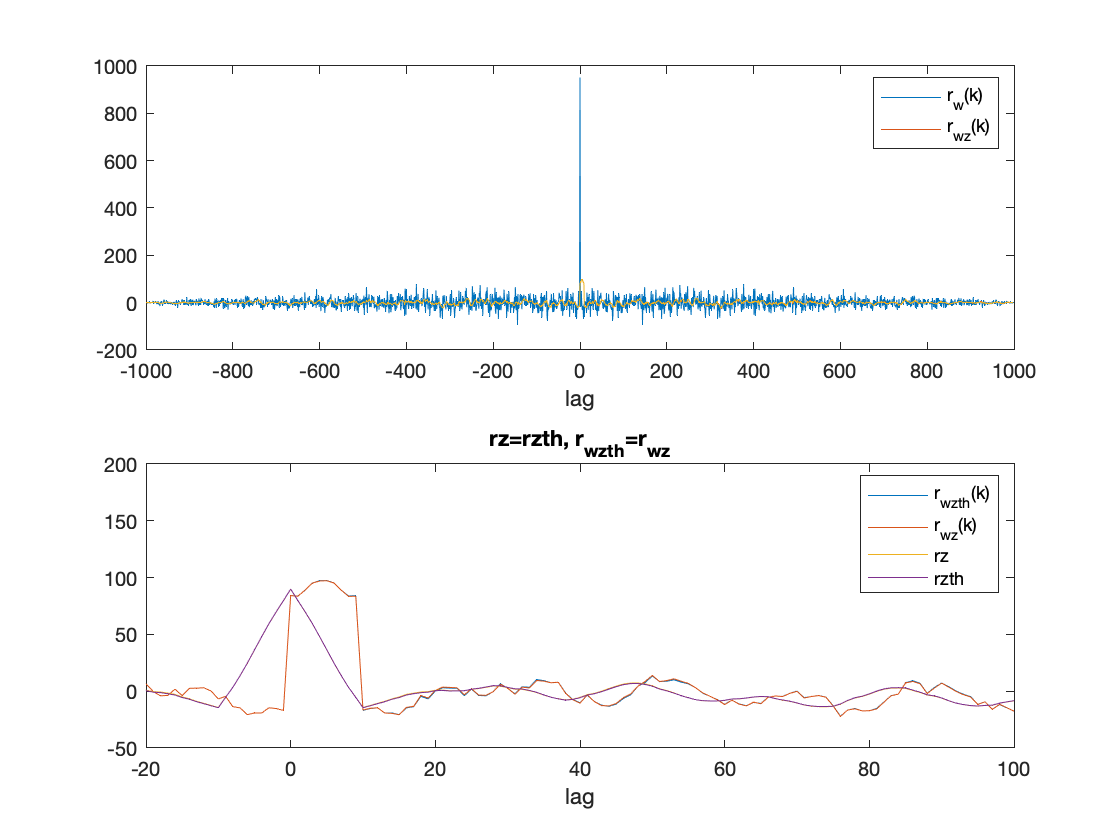

[rw, ~]  = xcorr(wn(2,:), wn(2,:)); % autocorrelation of wn 
[rz, ~]  = xcorr(zn(2,:), zn(2,:)); % autocorrelation of zn
[rwz, lag] = xcorr(zn(2,:), wn(2,:)); % intercorrelation between wn and zn

rwzth = conv(rw , h);
rwzth = rwzth(1:2*N-1);        % Take only part corresponding to the length of the signal

rzth = conv(fliplr(rwzth), h); %
rzth = rzth(1:2*N-1);          % Take only part corresponding to the length of the signal

figure
subplot(2,1,1)
    plot(lag, rw, ...
         lag, rwz, ...
         lag, rwzth)
    legend('r_w(k)', 'r_{wz}(k)')
    xlabel('lag')
subplot(2,1,2)
    plot(lag, rwzth, ...
         lag, rwz, ...
         lag, rz, ...
         lag, rzth)
    title('rz=rzth, r_{wzth}=r_{wz}')
    legend('r_{wzth}(k)', 'r_{wz}(k)','rz','rzth')
    xlabel('lag')
    xlim([-20 100])
    ylim([-50 200])